# Finding a 2D SSM for a von Kármán beam

This is an example of how to reconstruct a slow 2D SSM of a 6-degree of freedom mechanical system using synthetic measurements of the full state space. In this example, we consider a von Kármán beam with nonlinear damping discretized with 2 elements.

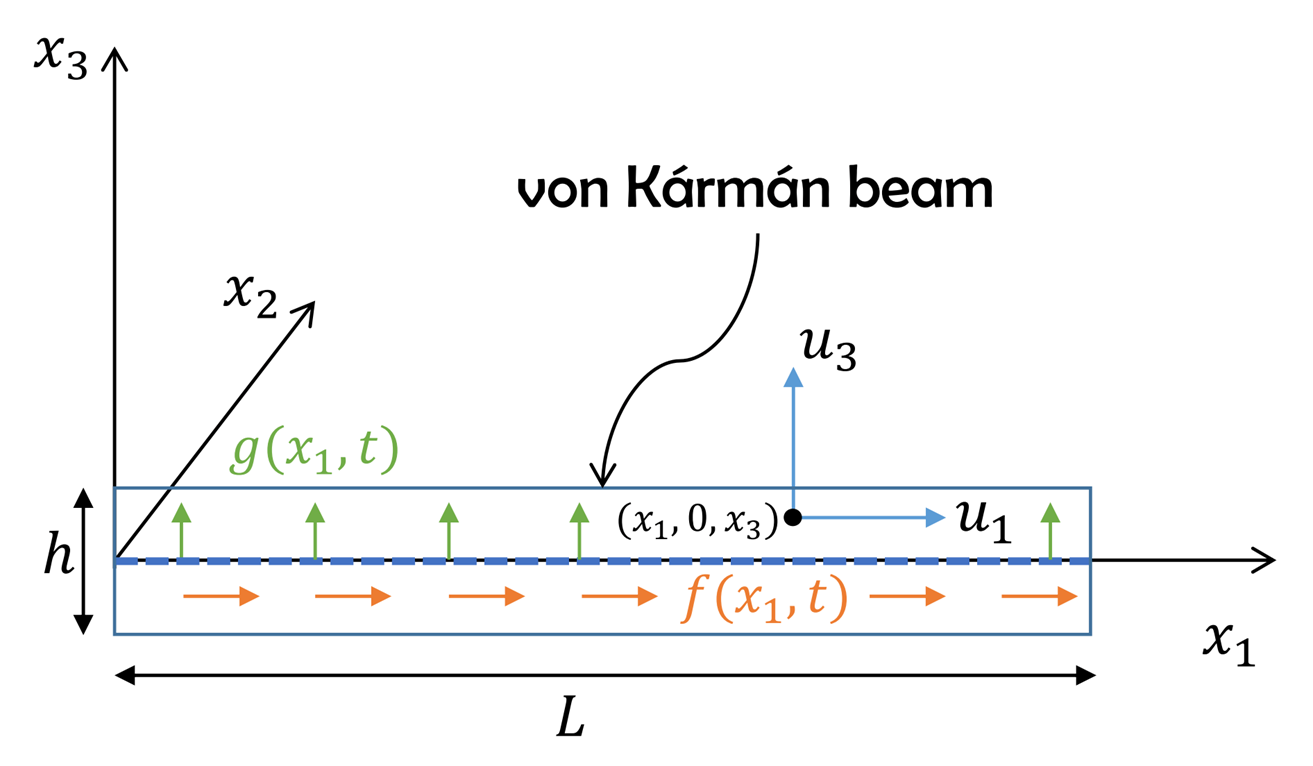

clearvars
close all

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) = \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $N\times N$ mass, stiffness, and damping matrices, respectively.

nTraj = 3;
nTrajsOnMfd = 1;
indTest = [1];
indTrain = setdiff(1:nTraj, indTest);
ICRadius = 0.0003;
SSMDim = 2;

nElements = 2;
E       = 70e9;   % 70e9 % Young's modulus
rho     = 2700;   % 2700 % density
nu      = 0.3;    % nu
kappa   = 1e8;    % material damping modulus

[M,C,K,fnl] = von_karman_model(nElements, E, rho, nu, kappa);

Building FE model
Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem
Assembling external force vector
Getting nonlinearity coefficients
Assembling Tensors
Total time spent on model assembly = 00:00:00


n = size(M,1);    % mechanical dofs (axial def, transverse def, angle)
[ICOnMfd, mfd, DS, SSM] = getSSMIC(M, C, K, fnl, nTrajsOnMfd, ICRadius, SSMDim, 1);

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 3.693254e-03
modal damping ratio for 2 mode is 2.333036e-02
modal damping ratio for 3 mode is 7.890752e-02
modal damping ratio for 4 mode is 2.290234e-01
modal damping ratio for 5 mode is 5.860662e+00

 The first 10 eigenvalues are given as 
   1.0e+04 *

  -0.0000 + 0.0005i
  -0.0000 - 0.0005i
  -0.0001 + 0.0033i
  -0.0001 - 0.0033i
  -0.0009 + 0.0110i
  -0.0009 - 0.0110i
  -0.0073 + 0.0312i
  -0.0073 - 0.0312i
  -0.0705 + 0.0000i
  -9.5467 + 0.0000i

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 4999297
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in r

ICOffMfd = ICRadius * pickPointsOnHypersphere(nTraj-nTrajsOnMfd, 2*n, 1);
IC = [ICOnMfd, ICOffMfd];
lambda = DS.spectrum.Lambda;

F = @(t,x) DS.odefun(t,x);

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0} 
& \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c} \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

Now we use SSMTool 2.0 [1] to compute a manifold tangent to the two slowest eigenmodes. We use the obtained manifold to set trajectory initial conditions that will lie close to it. We however do not use the computed manifold in the subsequent manifold fitting.

[1]  [https://github.com/haller-group/SSMTool-2.0/releases](https://github.com/haller-group/SSMTool-2.0/releases) 

## Generation of Synthetic Data

Having set up the dynamics of the problem, we now move on to generate synthetic data, which will be used to fit a parametrisation of the manifold. We will divide the data into a training set, for model fitting, and a test set, for validation. The data is generated by integrating the system.

observable = @(x) x;
tEnd = 100;
nSamp = 50000;
dt = tEnd/(nSamp-1);
sliceInt = [0.4*tEnd, Inf];
xSim = integrateTrajectories(F, observable, tEnd, nSamp, nTraj, IC);

simulating trajectory 1 of 3...
simulating trajectory 2 of 3...
simulating trajectory 3 of 3...


## Datadriven manifold fitting

The measured trajectories are assumed to lie close to a two-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the slowest pair of eigenvalues. We now want to fit a polynomial of order $M$ to the data points to approximate the manifold. Here we use a graph style parametrization, meaning that the manifold is parametrized using coordinates in the computed eigenspace. This excludes the possibility of folds on the manifold (however, if necessary we may circumvent this problem by increasing the dimensionality of the observed space). 

SSMOrder = 3;

xData = coordinates_embedding(xSim, SSMDim, 'ForceEmbedding', 1);

The embedding coordinates consist of the measured states.


The eigenspace $V_e$ of the two slowest modes is unknown in this case. Trajectories are assumed to lie close to an invariant manifold that is tangent to this eigenspace, as shown in the figure below.

 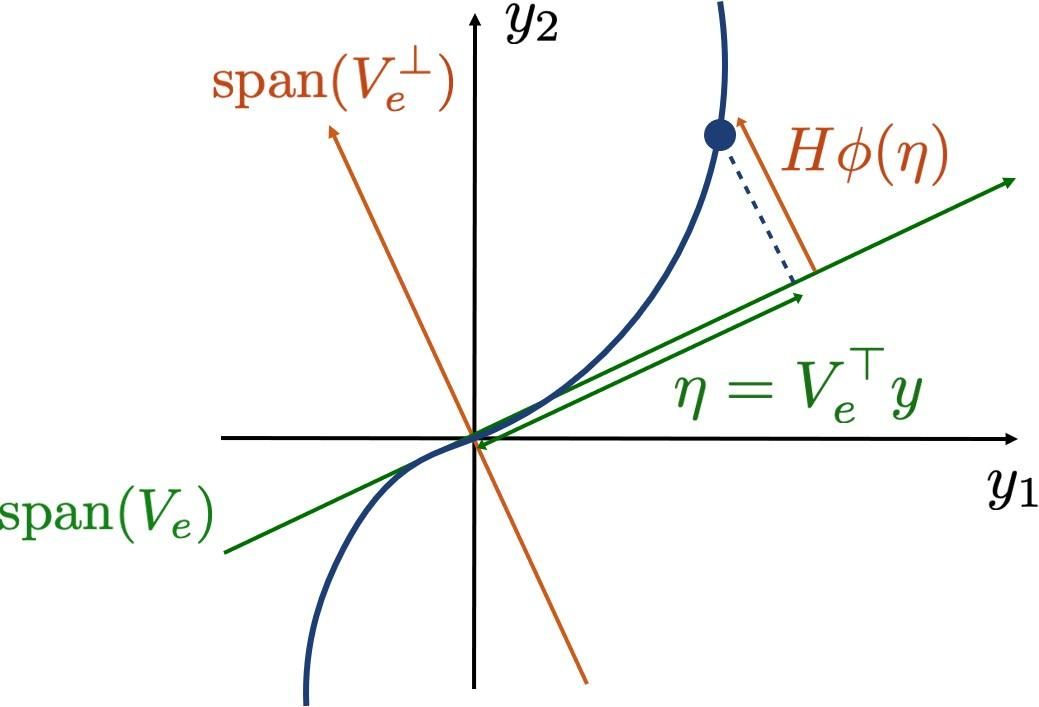

We therefore seek the $2N\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$y = V_e V_e^\top y + H \phi_{m,2:M}(V_e^\top y) $,

where the function $\phi_{m,2:M}(q)$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $q$. This optimization problem amounts to minimising a cost function computed from the measured data $y_k$,


$$C_r(V_e,H) = \sum_{k=1}^N ||y_k - V_eV_e^\top - H\phi_{m,2:M}(V_e^\top y_k) ||$$


to find $H$ and the $2N\times 2$ eigenspace matrix $V_e$, under the constraints that $V_e^\top H=0$ and $V_e^\top V_e = I$. The minimization is performed with the Matlab function `fmincon` in `IMparametrization`.

[V, SSMFunction, mfdInfo] = IMparametrization(xData(indTrain,:), SSMDim, SSMOrder, 'c1', 1000, 'c2', 0.1);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    1.421188e-12    9.961e-12    1.597e-13

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<

## Plot and validation

We plot the computed manifold embedding and calculate the deviation of the test data from the reduced model to evaluate the quality of model predictions.

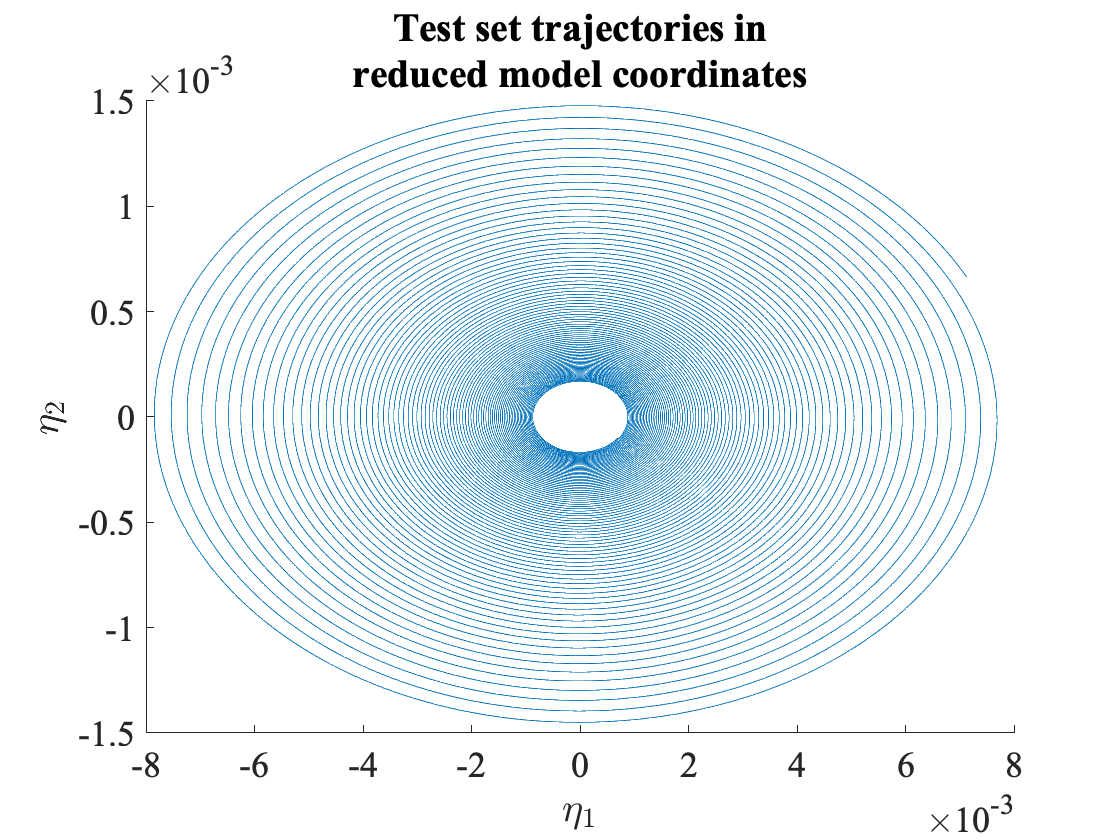

yData = getProjectedTrajs(xData, V);
plotReducedCoords(yData(indTest,:));


RRMS = getRMS(xData(indTest,:), SSMFunction, V)

RRMS = 7.2385e-05

RRMS is the root mean square error of the reconstruction.

We project the test set trajectory onto the manifold and compare the end tip displacement in the full state space and after projection.

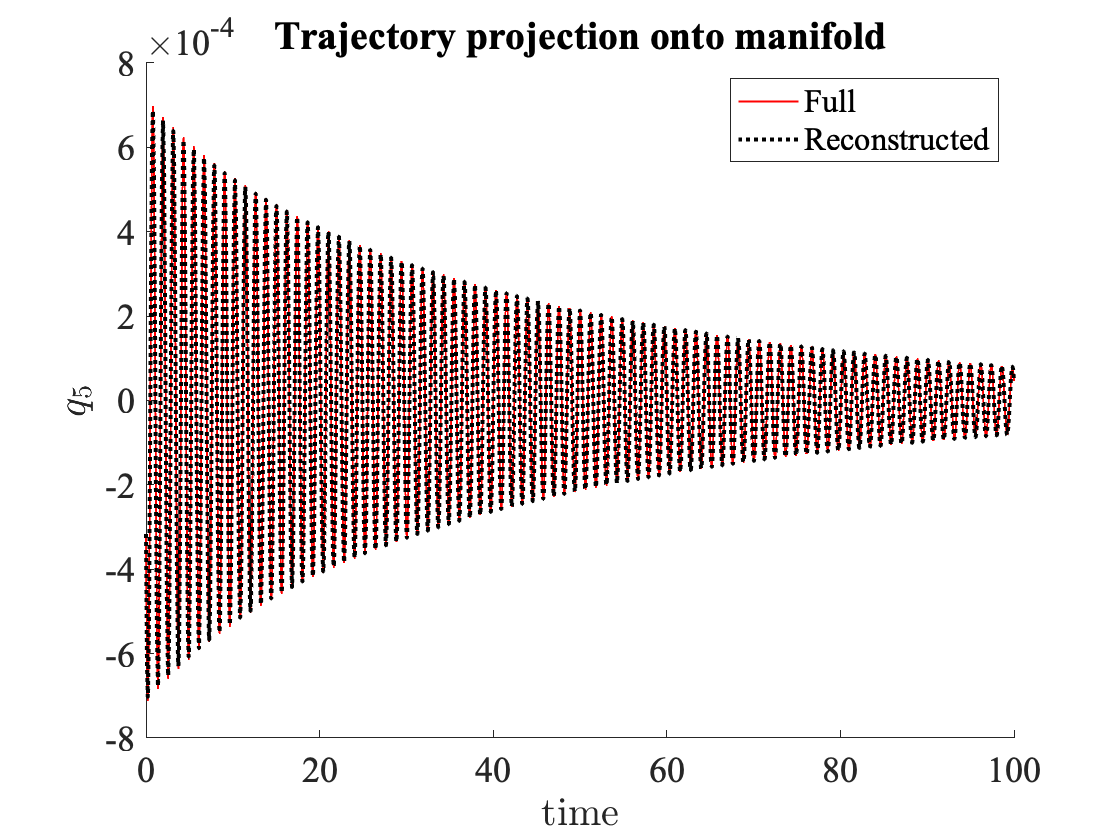

xLifted = liftReducedTrajs(yData, SSMFunction);
plotReconstructedTrajectory(xData(indTest(1),:), xLifted(indTest(1),:), n-1)

Furthermore, we draw the manifold shape along with the trajectories from the training set. The trajectories converge onto the slow manifold after vibrations in the modes of larger damping die out.

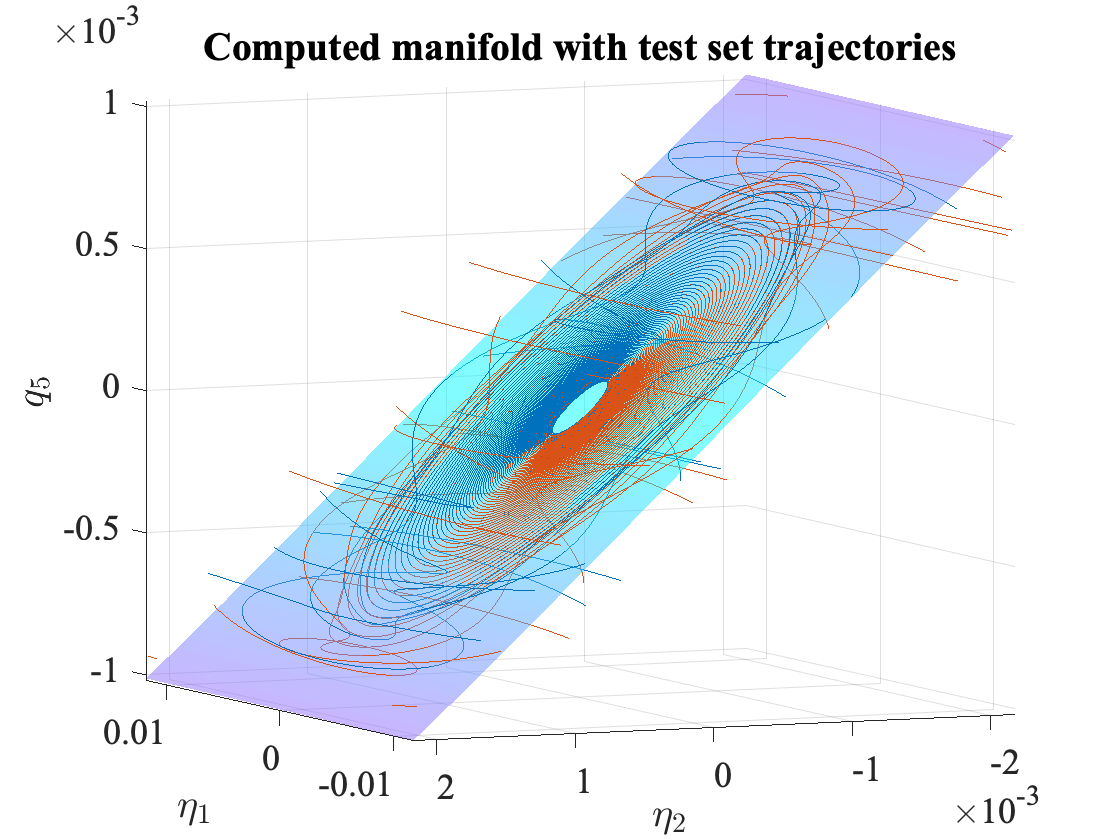

plotSSMWithTrajectories(xData(indTrain,:), SSMFunction, n-1, V, 50, 'SSMDimension', SSMDim)
xlim([-0.0118 0.0118])
ylim([-0.00217 0.00217])
zlim([-0.00102 0.00102])
view([-114 6.5])

## Reduced order model

We compute a model for the reduced dynamics with the training data projected onto the manifold. The function `IMdynamics_map `fits a polynomial map


$$y_{k+1} = W_r \phi(y_k)$$


where $\phi(y)$ again computes a vector of all monomials of $y$, and $W_r$ is a matrix of polynomial coefficients. 

We are also specifying that we want the reduced dynamics in normal form, so that the polynomial map will fulfill


$$z_{k+1} = N(z_k) \approx Dz_k + W_n\phi(z_k)$$


with $D$ a diagonal matrix and $W_n$ containing nonlinear terms, after a near-identity change of coordinates


$$z = T^{-1}(y) \approx y + W_t \phi(y)$$


[~,Tinv,N,T,NormalFormInfo] = IMdynamics_map(sliceTrajectories(yData(indTrain,:), sliceInt), 'R_PolyOrd', 3, 'style', 'normalform');

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1      3.50099e-10                       1.1e-06
     1           4      2.56641e-10             91       7.51e-07  
     2           5      1.75099e-10              1       2.18e-08  
     3           8      1.63092e-10             91       5.94e-08  
     4           9      6.61159e-11              1       3.17e-07  
     5          10      3.33431e-11              1       2.14e-07  
     6          11      2.55338e-11              1       4.42e-08  
     7          12      2.51708e-11              1       9.44e-09  

Local minimum found.

Optimization completed because the size of the gr

We transform the initial condition of our test trajectory according to the obtained change of coordinates, and use our reduced order model to predict the development of the trajectory. The error is computed as the average distance of the predicted trajectory to the actual one. RMSE is in the reduced model coordinates and RRMSE in the full state space.

zData = transformComplex(Tinv, yData);
[zRec, xRecNormal] = iterateMaps(N, zData, @(q) SSMFunction(T(q)));
yRecNormal = transformComplex(T, zRec);
[reducedTrajDist, fullTrajDist] = computeRecDynErrors(yRecNormal, xRecNormal, yData, xData);

RMSE_normal = mean(reducedTrajDist(indTest))

RMSE_normal = 0.0284

RRMSE_normal = mean(fullTrajDist(indTest))

RRMSE_normal = 0.0322

We plot the test set trajectory in the reduced coordinates and compare to the prediction. We also plot the measured and predicted tip displacement, and compare the estimated eigenvalues of the continuous evolution function to the ones computed with SSMTool. 

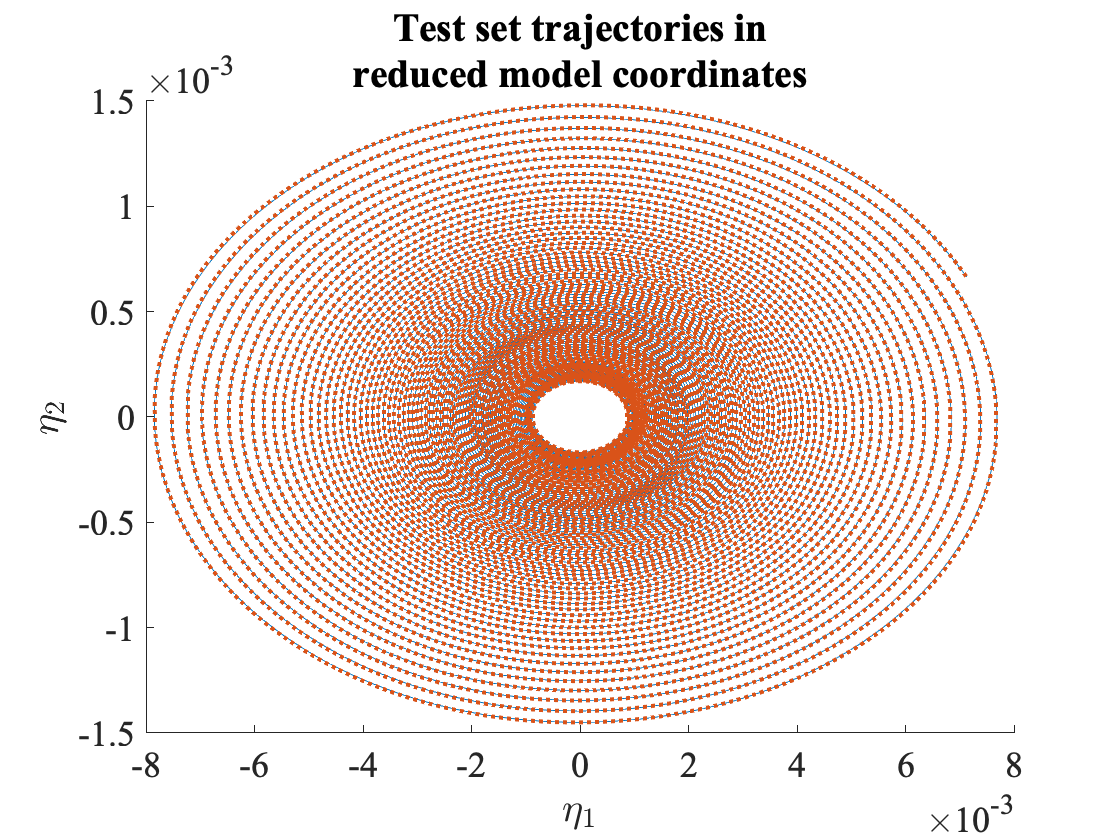

plotReducedCoords(yData(indTest(1),:), yRecNormal(indTest(1),:))

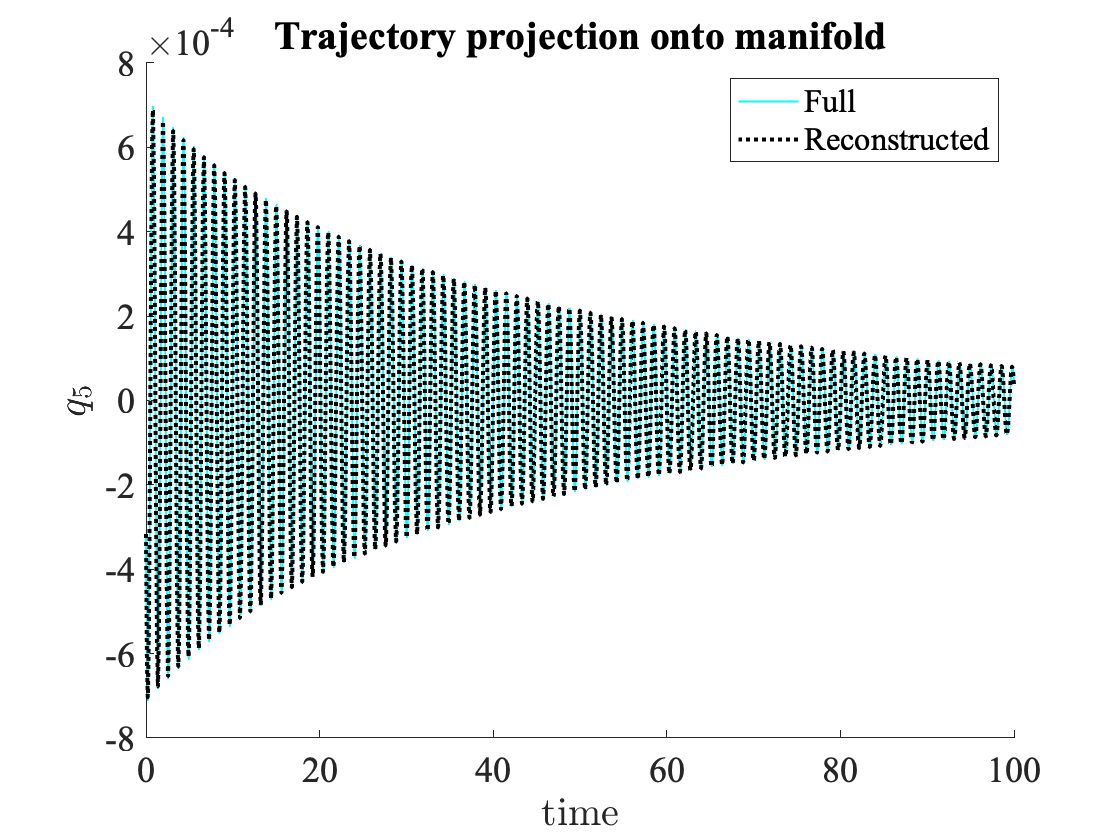

plotReconstructedTrajectory(xData(indTest(1),:), xRecNormal(indTest(1),:), n-1, 'c')


normalFormEigenvalues = computeEigenvaluesMap(NormalFormInfo, dt)

normalFormEigenvalues =   -0.0191 + 5.1642i
  -0.0191 - 5.1642i


DSEigenvalues = lambda(1:SSMDim)

DSEigenvalues =   -0.0191 + 5.1705i
  -0.0191 - 5.1705i


With the knowledge of the coefficients of the normal form, we extract backbone curves for the instantaneous damping and frequency.

N_info = NormalFormInfo.N;
[damp,freq] = nonres_normalform(N_info.coeff,N_info.exponents,dt);

The data-driven polar normal form dynamics reads:

                      1                      r2          
              _________________    ______________________

    Z(r) =    0.99991+0.010328i    -2.599e-05+0.00031746i

Notation: z = r*exp(1i*\theta) where r is the amplitude and \theta the phase; rk is the k-th power of r.
The polar form map  consists of r <--| |Z(r)|r and \theta <--| \theta  + \arg(Z(r))


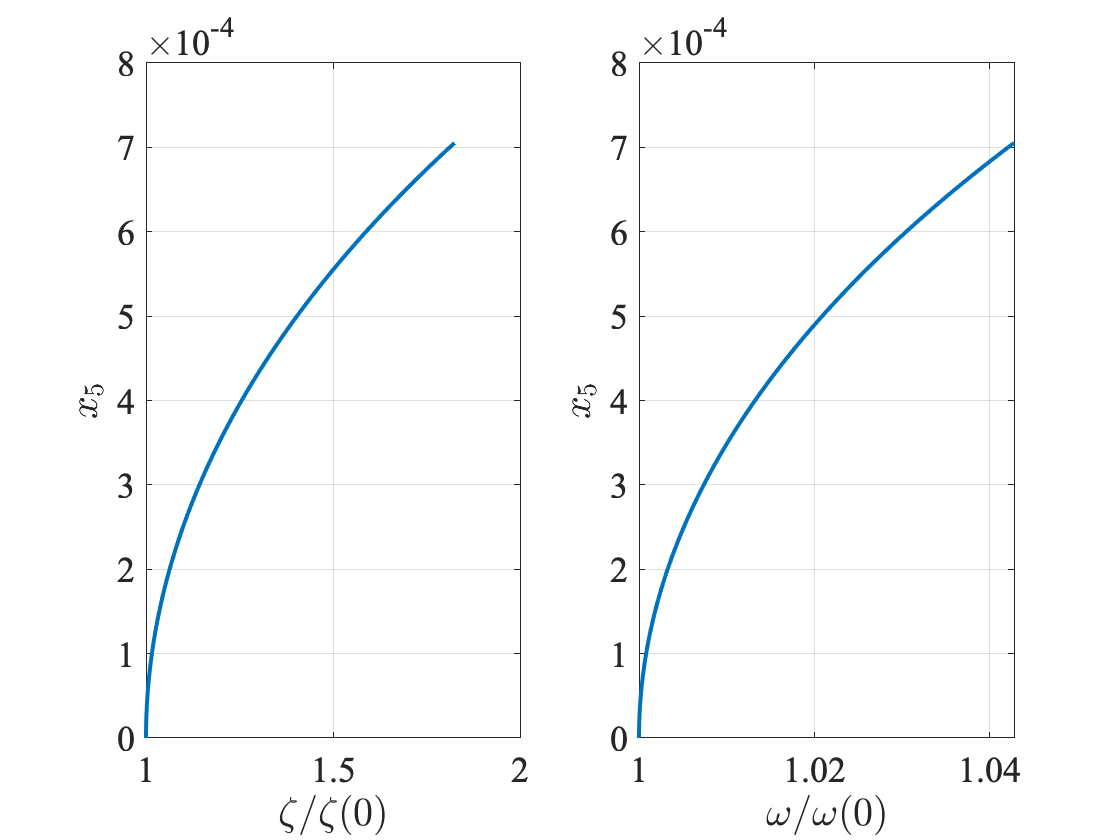

figure
maxRho = abs(zData{indTest(1),2}(1,1));
backbonecurves(damp, freq, SSMFunction, T, n-1, maxRho, 'norm');